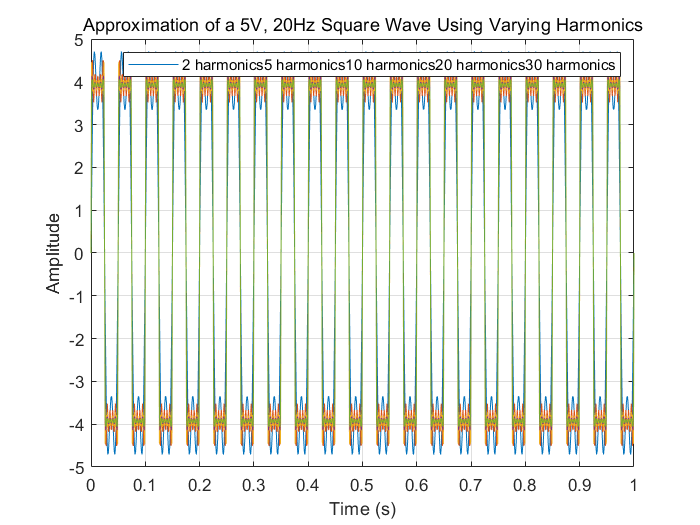

% 设置信号参数
fs = 1000;      % 采样频率
time = 0:1/fs:1;  % 时间轴
freq = 20;     % 基频
amp = 5;       % 幅值

% 创建时间向量
t = time;

% 不同谐波数量的列表
harmonicNum = [2 5 10 20 30];

% 初始化矩阵存储每种情况的近似方波
approxSquareWaves = zeros(length(t),length(harmonicNum));

% 对于每种谐波数量
for ii = 1:length(harmonicNum)
    numHarms = harmonicNum(ii);
    approxSquareWave = 0;
    % 累加至方波近似
    for jj = 1:numHarms
        approxSquareWave = approxSquareWave + (1/(2*jj-1)) * sine(t,(2*jj-1)*freq,amp);
    end
    approxSquareWaves(:,ii) = approxSquareWave;
end

% 绘制近似方波
figure;
plot(t,approxSquareWaves);
xlabel('Time (s)');
ylabel('Amplitude');
title('Approximation of a 5V, 20Hz Square Wave Using Varying Harmonics');
legend(strcat("2 harmonics","5 harmonics","10 harmonics","20 harmonics","30 harmonics"));
grid on;

function out = sine(t, harmFreq, amp)
    out = amp*sin(2*pi*harmFreq*t);
end